# FF_OPTIM_MZOOM_SAVEZRONE Derivative Multisection

**back to **[**Fan**](https://fanwangecon.github.io)**'s **[**Intro Math for Econ**](https://fanwangecon.github.io/Math4Econ/)**,  **[**Matlab Examples**](https://fanwangecon.github.io/M4Econ/)**, or **[**Dynamic Asset**](https://fanwangecon.github.io/CodeDynaAsset/)** Repositories**

This is the example vignette for function: [**ff_optim_mzoom_savezrone**](https://github.com/FanWangEcon//MEconTools/blob/master/MEconTools/optim/ff_optim_mzoom_savezrone.m) from the [**MEconTools Package**](https://fanwangecon.github.io/MEconTools/)**. **This functions solves for optimal savings/borrowing level given an anonymous function that provides the utility (not derivative) of a intertemporal savings problem. This is a vectorized function solves for multiple state-space elements at the same time. The function allows for controls of iteration counts, the number of evaluations per iteration, and how much to "zoom-in" for each iteration around the last iteration's maximum/optimal choice. 

Note that if first order conditions are available this method should not be used, but  [**ff_optim_mlsec_savezrone**](https://github.com/FanWangEcon//MEconTools/blob/master/MEconTools/optim/ff_optim_mlsec_savezrone.m) should be used. [**ff_optim_mlsec_savezrone**](https://github.com/FanWangEcon//MEconTools/blob/master/MEconTools/optim/ff_optim_mlsec_savezrone.m) relies on bisection.  In the first example below more *it_mzoom_jnt_pnts* values are needed to achieve the same precision than under [**ff_optim_mlsec_savezrone**](https://github.com/FanWangEcon//MEconTools/blob/master/MEconTools/optim/ff_optim_mlsec_savezrone.m)**.** However, increasing *it_mzoom_jnt_pnts* might not expensive given vectorization, should increase time cost linearly in generally. MZOOM is much more robust than bisection based methods. And by increasing the number of points evaluated per iteration, in limited number of iterations, the approximately exact optimal savings choice can be found.

The vectorized zooming savings problem rely on this function to solve for optimal savings choices:

- States Grid + Approximate Continuous Exact Savings (zoom) as Share of Cash-on-Hand ***Vectorized***: [**ff_vfi_az_zoom_vec**](https://github.com/FanWangEcon/MEconTools/blob/master/MEconTools/vfi/ff_vfi_az_zoom_vec.m), precision and speed

## Test FF_OPTIM_MZOOM_SAVEZRONE One Individual

Bisection for savings choice at one state:

% Generate the state-space and function
[fl_z1, fl_z2, fl_r, fl_beta] = deal(0.4730, 0.6252, 0.0839, 0.7365);
% ffi_intertemporal_max is a function in ff_optim_mlsec_savezrone for testing
fc_util = @(x) ffi_intertemporal_util(x, fl_z1, fl_z2, fl_r, fl_beta);
% Call Function
bl_verbose = false;
bl_timer = true;
% optimally borrowing given the parameters here
mp_mzoom_ctrlinfo = containers.Map('KeyType','char', 'ValueType','any');
mp_mzoom_ctrlinfo('it_mzoom_jnt_pnts') = 15;
mp_mzoom_ctrlinfo('it_mzoom_max_iter') = 10;
mp_mzoom_ctrlinfo('it_mzoom_zm_ratio') = 0.25;
[fl_opti_save_frac, fl_opti_save_level] = ...
    ff_optim_mzoom_savezrone(fc_util, bl_verbose, bl_timer, mp_mzoom_ctrlinfo)

Elapsed time is 0.004395 seconds.


fl_opti_save_frac = 0.4241

fl_opti_save_level = -0.1316

## Test FF_OPTIM_MZOOM_SAVEZRONE 4 Individuals 3 Iterations 50 Points Per Iteration

5 grid points per iteration, and 5 iterations.

    iter    cl_row_names_a      Var1        Var2        Var3        Var4  
    ____    ______________    ________    ________    ________    ________

     1        "point=1"          1e-05       1e-05       1e-05       1e-05
     1        "point=2"       0.020418    0.020418    0.020418    0.020418
     1        "point=3"       0.040826    0.040826    0.040826    0.040826
     1        "point=4"       0.061233    0.061233    0.061233    0.061233
     1        "point=5"       0.081641    0.081641    0.081641    0.081641
     1        "point=6"        0.10205     0.10205     0.10205     0.10205
     1        "point=7"        0.12246     0.12246     0.12246     0.12246
     1        "point=8"        0.14286     0.14286     0.14286     0.14286
     1        "point=9"        0.16327     0.

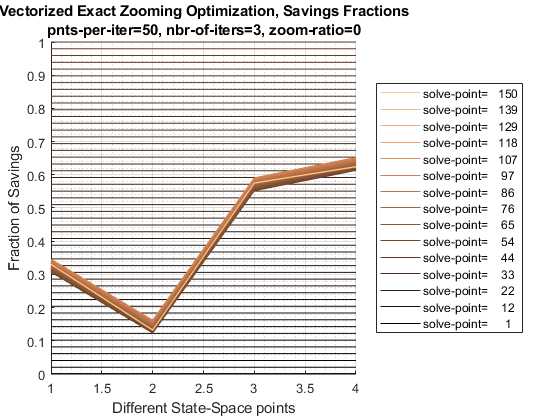

    iter    cl_row_names_a      Var1         Var2        Var3         Var4  
    ____    ______________    _________    ________    _________    ________

     1        "point=1"         -3.6912     -1.9565       -12.83     -14.789
     1        "point=2"        0.058694    -0.80561      -2.4984     -2.1254
     1        "point=3"         0.38043    -0.72015      -1.5784    -0.99337
     1        "point=4"         0.55947    -0.67935      -1.0493    -0.34024
     1        "point=5"         0.67979    -0.65711     -0.68055     0.11647
     1        "point=6"          0.7677    -0.64529     -0.39997     0.46531
     1        "point=7"          0.8349    -0.64026     -0.17534     0.74571
     1        "point=8"         0.88763     -0.6401     0.010483      0.9787
     1        "point=9"  

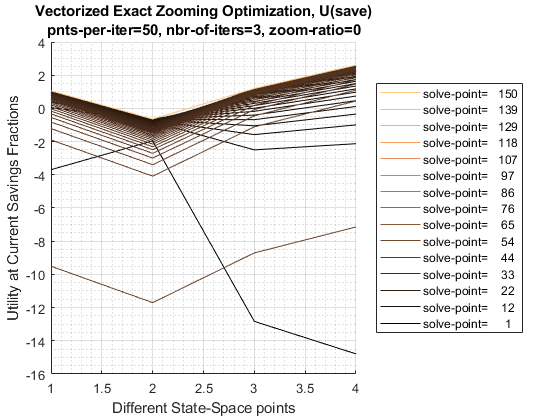

Elapsed time is 1.292487 seconds.
----------------------------------------
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
CONTAINER NAME: mp_container_map ND Array (Matrix etc)
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
                         i    idx    ndim    numel    rowN    colN     sum       mean      std      coefvari      min         max  
                         _    ___    ____    _____    ____    ____    ______    ______    ______    ________    ________    _______

    ar_opti_foc_obj      1     1      2        4       1       4      4.2243    1.0561    1.3298  

% Generate the state-space and function
rng(123);
it_draws = 4; % must be even number
ar_z1 = exp(rand([it_draws,1])*3-1.5);
ar_z2 = exp(rand([it_draws,1])*3-1.5);
ar_r = (rand(it_draws,1)*10.0);
ar_beta = [rand(round(it_draws/2),1)*0.9+0.1; rand(round(it_draws/2),1)*0.9+1]; 
fc_util = @(x) ffi_intertemporal_util(x, ar_z1, ar_z2, ar_r, ar_beta);
% Call Function
bl_verbose = true;
bl_timer = true;
mp_mzoom_ctrlinfo = containers.Map('KeyType','char', 'ValueType','any');
mp_mzoom_ctrlinfo('it_mzoom_jnt_pnts') = 50;
mp_mzoom_ctrlinfo('it_mzoom_max_iter') = 3;
mp_mzoom_ctrlinfo('it_mzoom_zm_ratio') = 0;
ff_optim_mzoom_savezrone(fc_util, bl_verbose, bl_timer, mp_mzoom_ctrlinfo);

## Test FF_OPTIM_MZOOM_SAVEZRONE 8 Individuals 3 Iterations 10 Points Per Iteration, 0.25 zoom in ratio

10 grid points per iteration, and 3 iterations.

    iter    cl_row_names_a     Var1       Var2       Var3       Var4       Var5       Var6       Var7       Var8  
    ____    ______________    _______    _______    _______    _______    _______    _______    _______    _______

     1        "point=1"         1e-05      1e-05      1e-05      1e-05      1e-05      1e-05      1e-05      1e-05
     1        "point=2"       0.11112    0.11112    0.11112    0.11112    0.11112    0.11112    0.11112    0.11112
     1        "point=3"       0.22223    0.22223    0.22223    0.22223    0.22223    0.22223    0.22223    0.22223
     1        "point=4"       0.33334    0.33334    0.33334    0.33334    0.33334   

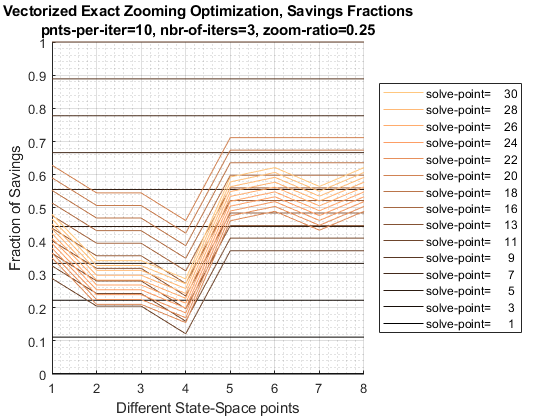

    iter    cl_row_names_a      Var1        Var2        Var3        Var4       Var5        Var6       Var7       Var8  
    ____    ______________    ________    ________    ________    ________    _______    ________    _______    _______

     1        "point=1"        -6.5286     -4.4312     -4.9951     -2.4407    -10.415     -15.025    -7.1352    -11.589
     1        "point=2"        0.34227    -0.90966      -1.148     0.28691     1.2451    -0.53687      2.835      1.245
     1        "point=3"         0.7287    -0.77242    -0.98657     0.36508     1.9879      0.4163      3.452     2.0751
     1        "point=4"        0.87872    -0.76818    -0.96

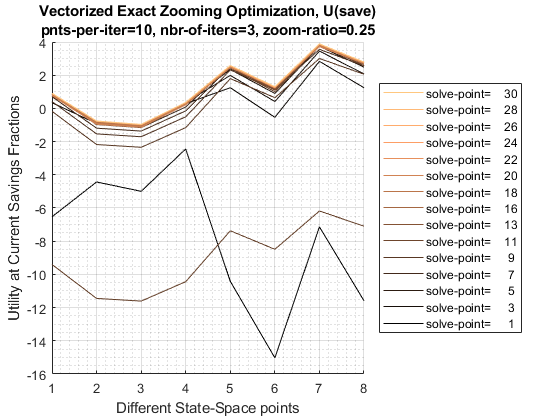

Elapsed time is 1.047404 seconds.
----------------------------------------
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
CONTAINER NAME: mp_container_map ND Array (Matrix etc)
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
                         i    idx    ndim    numel    rowN    colN     sum       mean        std      coefvari      min         max  
                         _    ___    ____    _____    ____    ____    ______    _______    _______    ________    ________    _______

    ar_opti_foc_obj      1     1      2        8       1       8      10.125     1.2656      1

% Generate the state-space and function
rng(123);
it_draws = 8; % must be even number
ar_z1 = exp(rand([it_draws,1])*3-1.5);
ar_z2 = exp(rand([it_draws,1])*3-1.5);
ar_r = (rand(it_draws,1)*10.0);
ar_beta = [rand(round(it_draws/2),1)*0.9+0.1; rand(round(it_draws/2),1)*0.9+1]; 
fc_util = @(x) ffi_intertemporal_util(x, ar_z1, ar_z2, ar_r, ar_beta);
% Call Function
bl_verbose = true;
bl_timer = true;
mp_mzoom_ctrlinfo = containers.Map('KeyType','char', 'ValueType','any');
mp_mzoom_ctrlinfo('it_mzoom_jnt_pnts') = 10;
mp_mzoom_ctrlinfo('it_mzoom_max_iter') = 3;
mp_mzoom_ctrlinfo('it_mzoom_zm_ratio') = 0.25;
ff_optim_mzoom_savezrone(fc_util, bl_verbose, bl_timer, mp_mzoom_ctrlinfo);

## Test FF_OPTIM_MZOOM_SAVEZRONE Speed

Test Speed doing 6.25 million state-spcae points for a savings problem:

% Generate the state-space and function
rng(123);
it_draws = 6250000; % must be even number
ar_z1 = exp(rand([it_draws,1])*3-1.5);
ar_z2 = exp(rand([it_draws,1])*3-1.5);
ar_r = (rand(it_draws,1)*10.0);
ar_beta = [rand(round(it_draws/2),1)*0.9+0.1; rand(round(it_draws/2),1)*0.9+1]; 
% ffi_intertemporal_max is a function in ff_optim_mlsec_savezrone for testing
fc_util = @(x) ffi_intertemporal_util(x, ar_z1, ar_z2, ar_r, ar_beta);
% Call Function
bl_verbose = false;
bl_timer = true;
% set parameters
mp_mzoom_ctrlinfo = containers.Map('KeyType','char', 'ValueType','any');
mp_mzoom_ctrlinfo('it_mzoom_jnt_pnts') = 20;
mp_mzoom_ctrlinfo('it_mzoom_max_iter') = 10;
mp_mzoom_ctrlinfo('it_mzoom_zm_ratio') = 0.25;
[ar_opti_save_frac, ar_opti_save_level] = ...
    ff_optim_mzoom_savezrone(fc_util, bl_verbose, bl_timer, mp_mzoom_ctrlinfo);

Elapsed time is 54.241104 seconds.


mp_container_map = containers.Map('KeyType','char', 'ValueType','any');
mp_container_map('ar_opti_save_frac') = ar_opti_save_frac;
mp_container_map('ar_opti_save_level') = ar_opti_save_level;
mp_container_map('ar_opti_save_frac_notnan') = ar_opti_save_frac(~isnan(ar_opti_save_frac));
ff_container_map_display(mp_container_map);

----------------------------------------
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
CONTAINER NAME: mp_container_map ND Array (Matrix etc)
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
                                i    idx    ndim     numel        rowN      colN       sum         mean        std      coefvari      min         max  
                                _    ___    ____    ________    ________    ____    __________    _______    _______    ________    ________    _______

    ar_opti_save_frac           1     1      2      6.25e+06    6.25e+06     1      2.8839e+

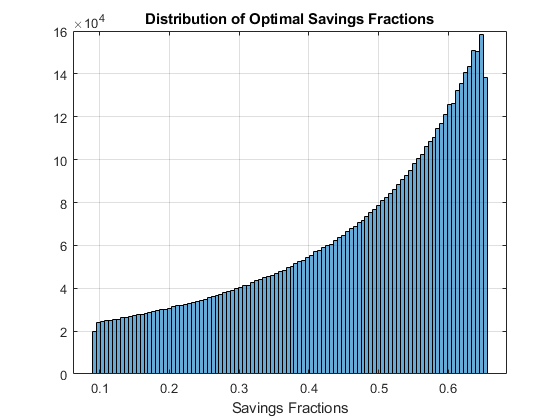

figure();
histogram(ar_opti_save_frac(~isnan(ar_opti_save_frac)),100);
title('Distribution of Optimal Savings Fractions');
xlabel('Savings Fractions');
grid on;

## Define Two Period Intertemporal  Log Utility No Shock Utility Function

See [Household’s Utility Maximization Problem and Two-Period Borrowing and Savings Problem given Endowments](https://fanwangecon.github.io/Math4Econ/derivative_application/htmlpdfm/K_save_households.html).

function [ar_util, ar_saveborr_level] = ...
    ffi_intertemporal_util(ar_saveborr_frac, z1, z2, r, beta)

ar_saveborr_level = ar_saveborr_frac.*(z1+z2./(1+r)) - z2./(1+r);
ar_util = log(z1 - ar_saveborr_level) + beta.*log(ar_saveborr_level.*(1+r) + z2);

end